syms r r1 theta varphi varphi1 l theta1 m M g

Las posiciones son:

posisionxcaja=r*cos(varphi)

$$posisionxcaja = r\,\cos\left(\phi \right)$$

posisionycaja= r*sin(varphi)

$$posisionycaja = r\,\sin\left(\phi \right)$$

Para el pendulo

posionpendulox=-r*cos(varphi)+l*sin(theta)*cos(varphi)

$$posionpendulox = l\,\cos\left(\phi \right)\,\sin\left(\theta \right)-r\,\cos\left(\phi \right)$$

posionpenduloy=-r*sin(varphi)+l*sin(theta)*sin(varphi)

$$posionpenduloy = l\,\sin\left(\theta \right)\,\sin\left(\phi \right)-r\,\sin\left(\phi \right)$$

posionpenduloz=l*cos(theta)

$$posionpenduloz = l\,\cos\left(\theta \right)$$

Aqui tenemos las velocidades en coordenadas esfericas, para encontrar cada velocidad

rxc=r1*cos(varphi)-r*sin(varphi)*varphi1;
ryc=r1*sin(varphi)+r*cos(varphi)*varphi1;
rxp =r1*cos(varphi)-r*sin(varphi)*varphi1+l*cos(varphi)*cos(theta)*theta1-l*sin(varphi)*sin(theta)*varphi1;
ryp=r1*sin(varphi)+r*cos(varphi)*varphi1+l*sin(varphi)*cos(theta)*theta1+l*cos(varphi)*sin(theta)*varphi1;
rzp=-l*sin(theta)*theta1;

Ahora sumamos y elevamos al cuadrado

v_caja2=rxc.^2+ryc.^2;
v_pendulo2=rxp.^2+ryp.^2+rzp.^2;

Encontramos las velocidades

v_pendulo2=simplify(v_pendulo2)

$$v\_pendulo2 = l^{2}\,{\theta_{1}}^{2}-l^{2}\,{\phi_{1}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\phi_{1}}^{2}+2\,\sin\left(\theta \right)\,l\,r\,{\phi_{1}}^{2}+2\,l\,r_{1}\,\theta_{1}\,\cos\left(\theta \right)+r^{2}\,{\phi_{1}}^{2}+{r_{1}}^{2}$$

v_caja2=simplify(v_caja2)

$$v\_caja2 = r^{2}\,{\phi_{1}}^{2}+{r_{1}}^{2}$$

Definimos la energia potencial y ahora calculamos el lagrangiano

v=m*g*l*cos(theta)

$$v = g\,l\,m\,\cos\left(\theta \right)$$

lagrangiano=expand(1/2*M*v_caja2+1/2*m*v_pendulo2)-v

$$lagrangiano = \frac{M\,{r_{1}}^{2}}{2}+\frac{m\,{r_{1}}^{2}}{2}+\frac{M\,r^{2}\,{\phi_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\theta_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\phi_{1}}^{2}}{2}+\frac{m\,r^{2}\,{\phi_{1}}^{2}}{2}-g\,l\,m\,\cos\left(\theta \right)-\frac{l^{2}\,m\,{\phi_{1}}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l\,m\,r\,{\phi_{1}}^{2}\,\sin\left(\theta \right)+l\,m\,r_{1}\,\theta_{1}\,\cos\left(\theta \right)$$

cinetica=expand(1/2*M*v_caja2+1/2*m*v_pendulo2)

$$cinetica = \frac{M\,{r_{1}}^{2}}{2}+\frac{m\,{r_{1}}^{2}}{2}+\frac{M\,r^{2}\,{\phi_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\theta_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\phi_{1}}^{2}}{2}+\frac{m\,r^{2}\,{\phi_{1}}^{2}}{2}-\frac{l^{2}\,m\,{\phi_{1}}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l\,m\,r\,{\phi_{1}}^{2}\,\sin\left(\theta \right)+l\,m\,r_{1}\,\theta_{1}\,\cos\left(\theta \right)$$

Calculamos los momentos conjugados

pr=diff(lagrangiano,r1)

$$pr = M\,r_{1}+m\,r_{1}+l\,m\,\theta_{1}\,\cos\left(\theta \right)$$

ptheta=diff(lagrangiano,theta1)

$$ptheta = m\,\theta_{1}\,l^{2}+m\,r_{1}\,\cos\left(\theta \right)\,l$$

pvarphi=diff(lagrangiano,varphi1)

$$pvarphi = l^{2}\,m\,\phi_{1}+m\,r^{2}\,\phi_{1}+M\,r^{2}\,\phi_{1}-l^{2}\,m\,\phi_{1}\,{\cos\left(\theta \right)}^{2}+2\,l\,m\,r\,\phi_{1}\,\sin\left(\theta \right)$$

El hamiltoniano esta dado por, que simplificandolo obtenemos

hamiltoniano=pr*r1+ptheta*theta1+pvarphi*varphi1-lagrangiano;
hamiltoniano=simplify(hamiltoniano)

$$hamiltoniano = \frac{M\,{r_{1}}^{2}}{2}+\frac{m\,{r_{1}}^{2}}{2}+\frac{M\,r^{2}\,{\phi_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\theta_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\phi_{1}}^{2}}{2}+\frac{m\,r^{2}\,{\phi_{1}}^{2}}{2}+g\,l\,m\,\cos\left(\theta \right)-\frac{l^{2}\,m\,{\phi_{1}}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l\,m\,r\,{\phi_{1}}^{2}\,\sin\left(\theta \right)+l\,m\,r_{1}\,\theta_{1}\,\cos\left(\theta \right)$$

Reescribimos usando los momentos conjugados, definiendo entonces las nuevas variables, notando que los momentos multiplicados por su varibale canonica y divido entre dos, la parte de energia cinetica del lagrangiano.

expand((pr*r1)/2), expand(ptheta*theta1/2), expand(pvarphi*varphi1/2)

$$ans = \frac{M\,{r_{1}}^{2}}{2}+\frac{m\,{r_{1}}^{2}}{2}+\frac{l\,m\,r_{1}\,\theta_{1}\,\cos\left(\theta \right)}{2}$$

$$ans = \frac{m\,l^{2}\,{\theta_{1}}^{2}}{2}+\frac{m\,r_{1}\,\cos\left(\theta \right)\,l\,\theta_{1}}{2}$$

$$ans = \frac{M\,r^{2}\,{\phi_{1}}^{2}}{2}+\frac{l^{2}\,m\,{\phi_{1}}^{2}}{2}+\frac{m\,r^{2}\,{\phi_{1}}^{2}}{2}-\frac{l^{2}\,m\,{\phi_{1}}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l\,m\,r\,{\phi_{1}}^{2}\,\sin\left(\theta \right)$$

Podemos escribir el hamiltoniano como

anterior_Hamilton=hamiltoniano; %guardamos el anterior hamiltoniano
syms p_r p_theta p_varphi
hamiltoniano=p_r*r1/2+p_theta*theta1/2+p_varphi*varphi1/2+m*g*l*cos(theta) %#ok<NASGU> 

$$hamiltoniano = \frac{p_{r}\,r_{1}}{2}+\frac{p_{\theta }\,\theta_{1}}{2}+\frac{p_{\phi }\,\phi_{1}}{2}+g\,l\,m\,\cos\left(\theta \right)$$

Ahora, con los datos obtenidos de las varibles canonicas, despejamos las derivadas de r, $\varphi$, y $\theta$. Obtenemos entonces que:

theta1=(p_theta*(m+M)-p_r*cos(theta)*l*m)/(m^2*l^2+m*M*l^2-l^2*m^2*(cos(theta)).^2)

$$theta1 = \frac{p_{\theta }\,\left(M+m\right)-l\,m\,p_{r}\,\cos\left(\theta \right)}{-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m}$$

r1=(p_theta*cos(theta)-p_r*l)/(m*cos(theta)^2*l-l*(m+M))

$$r1 = \frac{l\,p_{r}-p_{\theta }\,\cos\left(\theta \right)}{l\,\left(M+m\right)-l\,m\,{\cos\left(\theta \right)}^{2}}$$

varphi1=p_varphi/(l^2*m+m*r^2+M*r^2-l^2*m*cos(theta)^2+2*l*m*r*sin(theta))

$$varphi1 = \frac{p_{\phi }}{M\,r^{2}+l^{2}\,m+m\,r^{2}-l^{2}\,m\,{\cos\left(\theta \right)}^{2}+2\,l\,m\,r\,\sin\left(\theta \right)}$$

Con lo que el hamiltoniano nos queda como

hamiltoniano=p_r*r1/2+p_theta*theta1/2+p_varphi*varphi1/2+m*g*l*cos(theta)

$$hamiltoniano = \frac{{p_{\phi }}^{2}}{2\,\left(M\,r^{2}+l^{2}\,m+m\,r^{2}-l^{2}\,m\,{\cos\left(\theta \right)}^{2}+2\,l\,m\,r\,\sin\left(\theta \right)\right)}+\frac{p_{r}\,\left(l\,p_{r}-p_{\theta }\,\cos\left(\theta \right)\right)}{2\,\left(l\,\left(M+m\right)-l\,m\,{\cos\left(\theta \right)}^{2}\right)}+\frac{p_{\theta }\,\left(p_{\theta }\,\left(M+m\right)-l\,m\,p_{r}\,\cos\left(\theta \right)\right)}{2\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m\right)}+g\,l\,m\,\cos\left(\theta \right)$$

Las ecucaciones de hamilton son


$$\frac{\partial \mathcal{H}}{dp_i}=\dot{q}_i \;\;\;\; \dot{p}_i=\frac{\partial \mathcal{h}}{dq_i} + Q_i$$


donde $Q_i$ es una fuerza generalizada, para este caso, tenemos una fuerza en la caja en la dirección r, te tal forma que cuando el pendulo baja, la caja es "empujada"

Procedemos ahora a calcular las ecuaciones de hamilton que generan nuestro sistema:

syms f
p_r1=-simplify(diff(hamiltoniano,r))+f, r1=simplify(diff(hamiltoniano,p_r))

$$p\_r1 = f+\frac{{p_{\phi }}^{2}\,\left(2\,M\,r+2\,m\,r+2\,l\,m\,\sin\left(\theta \right)\right)}{2\,{\left(M\,r^{2}+m\,r^{2}+l^{2}\,m\,{\sin\left(\theta \right)}^{2}+2\,l\,m\,r\,\sin\left(\theta \right)\right)}^{2}}$$

$$r1 = \frac{l\,p_{r}-p_{\theta }\,\cos\left(\theta \right)}{l\,\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}$$

p_theta1=-simplify(diff(hamiltoniano,theta)), theta1=simplify(diff(hamiltoniano,p_theta))

$$p\_theta1 = \begin{array}{l} g\,l\,m\,\sin\left(\theta \right)-\frac{p_{r}\,p_{\theta }\,\sin\left(\theta \right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)}+\frac{l\,m\,{p_{\phi }}^{2}\,\left(2\,r\,\cos\left(\theta \right)+2\,l\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{2\,{\left(M\,r^{2}+m\,r^{2}+l^{2}\,m\,{\sin\left(\theta \right)}^{2}+2\,l\,m\,r\,\sin\left(\theta \right)\right)}^{2}}+\frac{p_{\theta }\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(M\,p_{\theta }+m\,p_{\theta }-l\,m\,p_{r}\,\cos\left(\theta \right)\right)}{l^{2}\,\sigma_{1}}+\frac{m\,p_{r}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(l\,p_{r}-p_{\theta }\,\cos\left(\theta \right)\right)}{l\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}^{2} \end{array}$$

$$theta1 = \frac{M\,p_{\theta }+m\,p_{\theta }-l\,m\,p_{r}\,\cos\left(\theta \right)}{l^{2}\,m\,\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}$$

p_varphi1=-simplify(diff(hamiltoniano,varphi)), varphi1=simplify(diff(hamiltoniano,p_varphi))

$$p\_varphi1 = 0$$

$$varphi1 = \frac{p_{\phi }}{M\,r^{2}+m\,r^{2}+l^{2}\,m\,{\sin\left(\theta \right)}^{2}+2\,l\,m\,r\,\sin\left(\theta \right)}$$

Ahora vamos a resolver nuestro sistema de ecuaciones diferenciales, donde tendremos 7 variables de estado


$$r=x(1), \;\; \varphi=x(2), \;\; \theta=x(3), \;\; p_r= x(4), \;\; p_\varphi = x(5), \;\; p_\theta=x(6), \;\; f(t) = x(7)$$


La fuerza con la que es empujada la caja, tiene la siguiente forma


$$f=mg\sin(\theta),\;\;\; f\prime = mg\cos(\theta)$$


Escribimos entonces las ecuaciones en el lenguaje para que matlab las pueda resolver

l=1;m=1; M=2;  g=9.8;
funcion=@(t,x)[((l*x(4)-x(6)*cos(x(3)))./(l*(-m*cos(x(3))^2+M+m)));...
               (x(5)/(M*(x(1))^2+m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*x(1)*sin(x(3))));...
               ((M*x(6)+m*x(6)-l*m*x(4)*cos(x(3)))./(l^2*m*(-m*cos(x(3))^2+m+M)));...
               ((x(5))^2*(M*x(1)+m*x(1)+l*m*sin(x(3))))/(M*(x(1))^2+m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*(x(1))*sin(x(3))^2)-m*g*sin(x(1));...
               0;...
               g*l*m*sin(x(3))-(x(4)*x(6)*sin(x(3)))/(l*(m*sin(x(3))^2+M))+(l*m*(x(5))^2*(x(1)*cos(x(3))+l*cos(x(3))*sin(x(3))))/(M*(x(1))^2+...
               m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*x(1)*sin(x(3))^2)+(x(6)*cos(x(3))*sin(x(3))*(M*x(6)+m*x(6)-...
               l*m*x(4)*cos(x(3))))/(l^2*(-m*cos(x(3))^2+M+m))+(m*x(4)*cos(x(3))*sin(x(3))*(l*x(4)-x(6)*cos(x(3))))/(l*(-m*cos(x(3))^2+...
               M+m));...
               m*g*cos(x(3))]

funcion = function_handle with value:
    @(t,x)[((l*x(4)-x(6)*cos(x(3)))./(l*(-m*cos(x(3))^2+M+m)));(x(5)/(M*(x(1))^2+m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*x(1)*sin(x(3))));((M*x(6)+m*x(6)-l*m*x(4)*cos(x(3)))./(l^2*m*(-m*cos(x(3))^2+m+M)));((x(5))^2*(M*x(1)+m*x(1)+l*m*sin(x(3))))/(M*(x(1))^2+m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*(x(1))*sin(x(3))^2)-m*g*sin(x(1));0;g*l*m*sin(x(3))-(x(4)*x(6)*sin(x(3)))/(l*(m*sin(x(3))^2+M))+(l*m*(x(5))^2*(x(1)*cos(x(3))+l*cos(x(3))*sin(x(3))))/(M*(x(1))^2+m*(x(1))^2+l^2*m*sin(x(3))^2+2*l*m*x(1)*sin(x(3))^2)+(x(6)*cos(x(3))*sin(x(3))*(M*x(6)+m*x(6)-l*m*x(4)*cos(x(3))))/(l^2*(-m*cos(x(3))^2+M+m))+(m*x(4)*cos(x(3))*sin(x(3))*(l*x(4)-x(6)*cos(x(3))))/(l*(-m*cos(x(3))^2+M+m));m*g*cos(x(3))]


rvt=linspace(0,10,2^10);
ci=[0 0 deg2rad(60) 0 0.3 0 0]

ci =          0         0    1.0472         0    0.3000         0         0


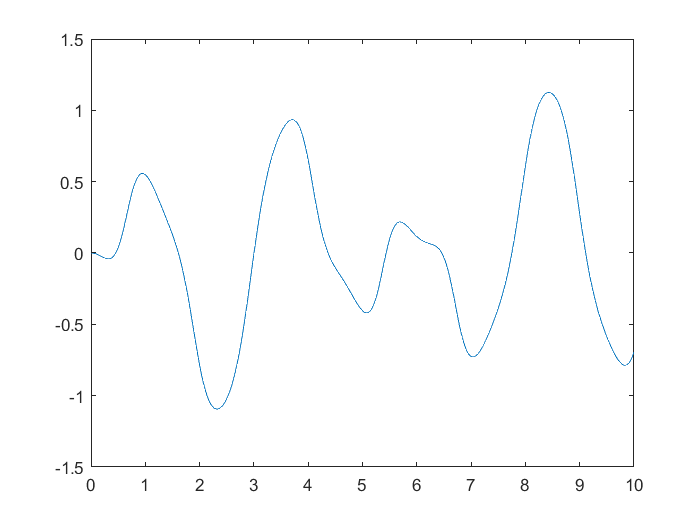

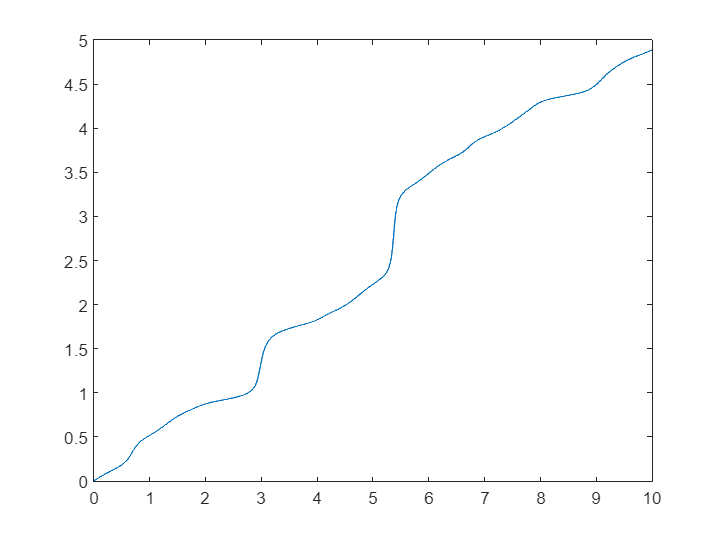

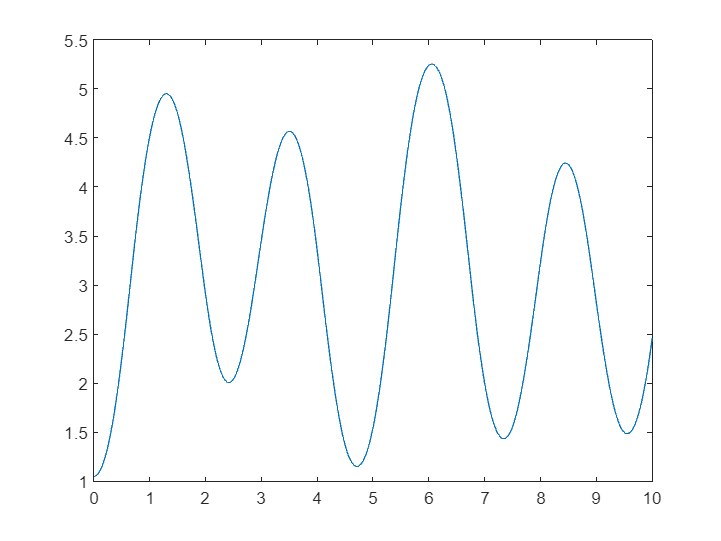

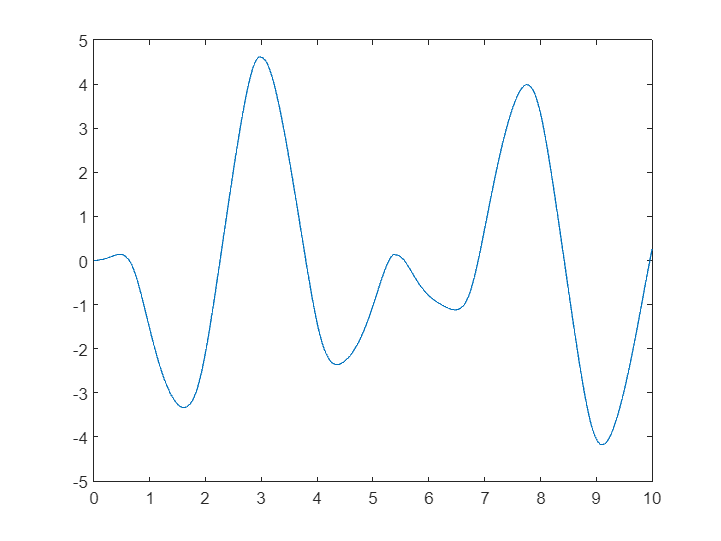

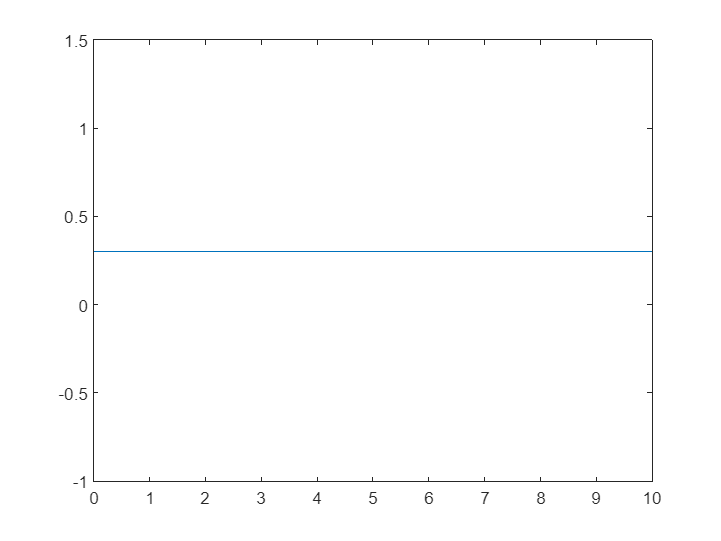

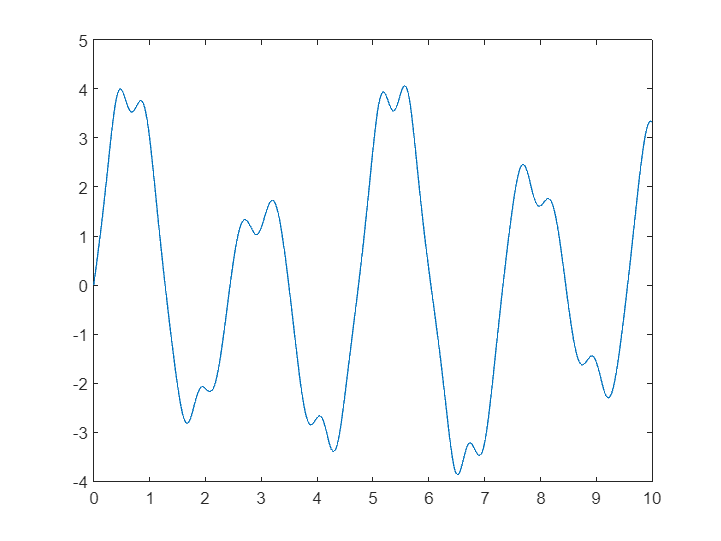

[t,x]=ode45(funcion,rvt,ci);
for i=1:6
    figure
    plot(t,x(:,i))
end